clear
fastAccess_chunksize_010_xdf = load_xdf("Z:\ting\shared_ting\Yifei\Recordings\Exp_test_5.xdf", 'HandleJitterRemoval', 0);
fastAccess_chunksize_005_xdf = load_xdf("Z:\ting\shared_ting\Yifei\Recordings\Exp_test_6.xdf", 'HandleJitterRemoval', 0);
fastAccess_chunksize_002_xdf = load_xdf("Z:\ting\shared_ting\Yifei\Recordings\Exp_test_7.xdf", 'HandleJitterRemoval', 0);
fastAccess_chunksize_050_xdf = load_xdf("Z:\ting\shared_ting\Yifei\Recordings\Exp_test_8.xdf", 'HandleJitterRemoval', 0);
fastAccess_chunksize_100_xdf = load_xdf("Z:\ting\shared_ting\Yifei\Recordings\Exp_test_9.xdf", 'HandleJitterRemoval', 0);

% sampling rate abnormality
effective_srate_010 = fastAccess_chunksize_010_xdf{1, 1}.info.effective_srate;
nominal_srate_010 = str2double(fastAccess_chunksize_010_xdf{1, 1}.info.nominal_srate);
abnormality_010 = (abs(nominal_srate_010 - effective_srate_010) / nominal_srate_010) * 100 % in percentage

abnormality_010 = 0.0658

effective_srate_005 = fastAccess_chunksize_005_xdf{1, 2}.info.effective_srate;
nominal_srate_005 = str2double(fastAccess_chunksize_005_xdf{1, 2}.info.nominal_srate);
abnormality_005 = (abs(nominal_srate_005 - effective_srate_005) / nominal_srate_005) * 100 % in percentage

abnormality_005 = 0.0040

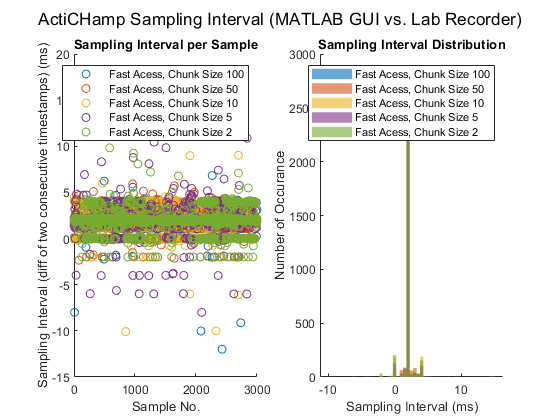

timestamps_100 = fastAccess_chunksize_100_xdf{1, 2}.time_stamps(1 : 3001);
sampling_interval_100 = diff(timestamps_100);

timestamps_050 = fastAccess_chunksize_050_xdf{1, 2}.time_stamps(1 : 3001);
sampling_interval_050 = diff(timestamps_050);

timestamps_010 = fastAccess_chunksize_010_xdf{1, 1}.time_stamps(1 : 3001);
sampling_interval_010 = diff(timestamps_010);

timestamps_005 = fastAccess_chunksize_005_xdf{1, 2}.time_stamps(1 : 3001);
sampling_interval_005 = diff(timestamps_005);

timestamps_002 = fastAccess_chunksize_002_xdf{1, 2}.time_stamps(1 : 3001);
sampling_interval_002 = diff(timestamps_002);

str_legend = ["Fast Acess, Chunk Size 100", "Fast Acess, Chunk Size 50", "Fast Acess, Chunk Size 10", "Fast Acess, Chunk Size 5", "Fast Acess, Chunk Size 2"];
binEdges = linspace(-10, 15, 50);
% plot
figure;
subplot(1, 2, 1)
hold on
scatter(1 : 3000, sampling_interval_100 .* 1e3, 'XJitter', 'randn')
scatter(1 : 3000, sampling_interval_050 .* 1e3, 'XJitter', 'randn')
scatter(1 : 3000, sampling_interval_010 .* 1e3, 'XJitter', 'randn')
scatter(1 : 3000, sampling_interval_005 .* 1e3, 'XJitter', 'randn')
scatter(1 : 3000, sampling_interval_002 .* 1e3, 'XJitter', 'randn')
hold off
legend(str_legend)
xlabel("Sample No.")
ylabel("Sampling Interval (diff of two consecutive timestamps) (ms)")
title("Sampling Interval per Sample")
subplot(1, 2, 2)
hold on
histogram(sampling_interval_100 * 1e3, binEdges, 'EdgeColor', 'none')
histogram(sampling_interval_050 * 1e3, binEdges, 'EdgeColor', 'none')
histogram(sampling_interval_010 * 1e3, binEdges, 'EdgeColor', 'none')
histogram(sampling_interval_005 * 1e3, binEdges, 'EdgeColor', 'none')
histogram(sampling_interval_002 * 1e3, binEdges, 'EdgeColor', 'none')
hold off
legend(str_legend)
xlabel("Sampling Interval (ms)")
ylabel("Number of Occurance")
title("Sampling Interval Distribution")
sgtitle("ActiCHamp Sampling Interval (MATLAB GUI vs. Lab Recorder)")

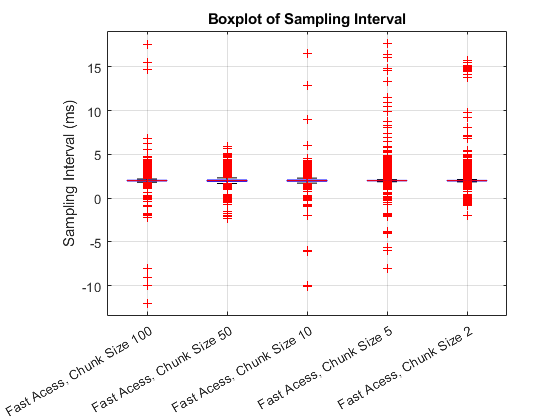

intervals = [sampling_interval_100', sampling_interval_050', sampling_interval_010', sampling_interval_005', sampling_interval_002'] .* 1e3;
figure
boxplot(intervals, 'Labels', str_legend)
grid on
ylabel("Sampling Interval (ms)")
title("Boxplot of Sampling Interval")